load("sampleEEGdata.mat");

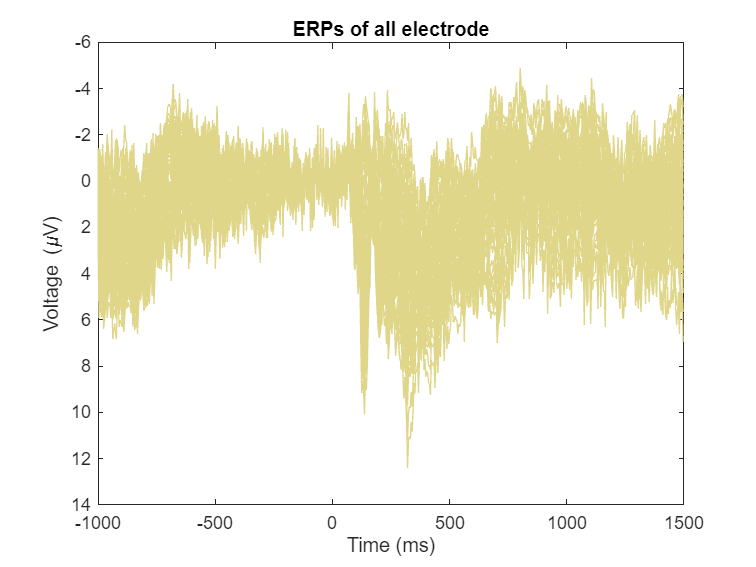

%%Computing ERP at each electrode
figure;
erpTable = squeeze(mean(EEG.data,3));
plot(EEG.times, erpTable, Color="#E0D68A")
title('ERPs of all electrode')
ylabel('Voltage (\muV)')
xlabel('Time (ms)')
axis ij
hold off

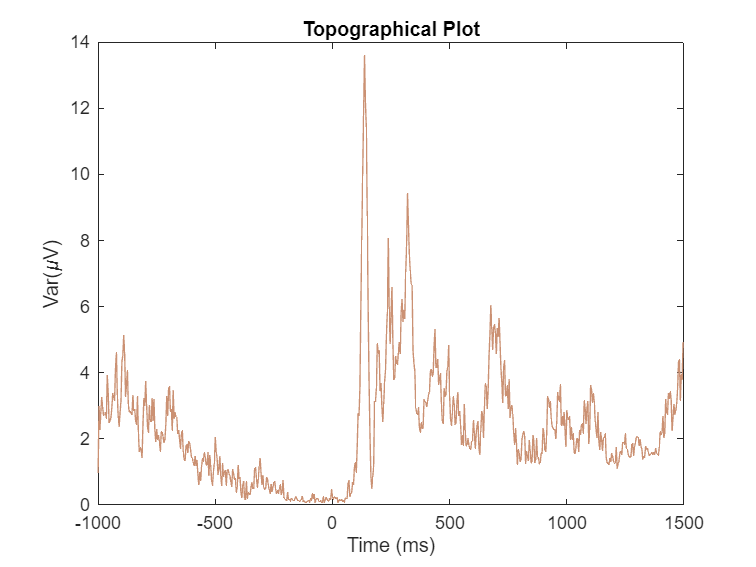

figure;
plot(EEG.times, var(erpTable), Color="#CB9173")
title("Topographical Plot")
ylabel('Var(\muV)')
xlabel('Time (ms)')

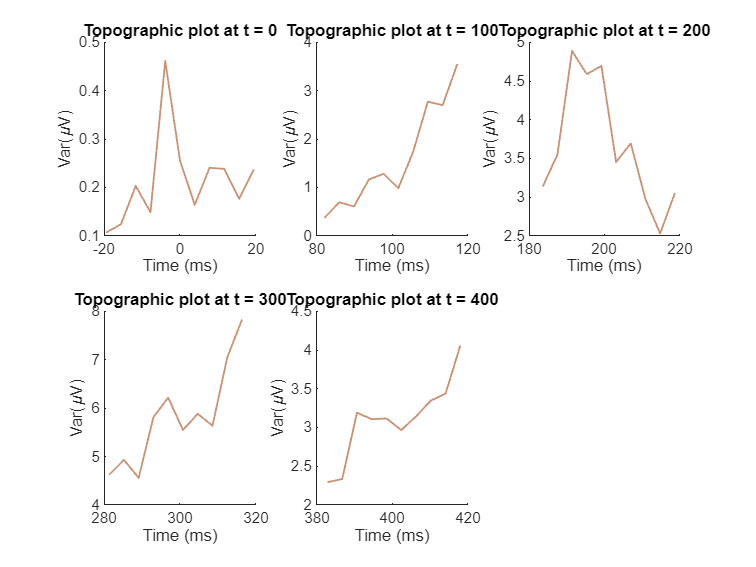

time_points = 0:100:400;
buffer = 20;

figure;
for i = 1:length(time_points)
    subplot(2,3,i)

    lb = find(EEG.times >= time_points(i) - buffer, 1);
    ub = find(EEG.times <= time_points(i) + buffer, 1,"last");

    mean_w = erpTable(:,lb:ub);
    % plot(EEG.times(lb:ub),erpTable(:,lb:ub), Color="#E0D68A")
    hold on
    var_w = var(mean_w);
    plot(EEG.times(lb:ub), var_w, Color="#CB9173", LineWidth=1)
    title("Topographic plot at t = "+time_points(i))
    ylabel("Var(\muV)")
    xlabel("Time (ms)")
end